In =      1     0     0
     0     1     0
     0     0     1


$$A = \left(\begin{array}{ccc} 0 & 1 & 0\\ \frac{{X_{3}}^{2}\,c}{{X_{1}}^{2}\,m} & 0 & -\frac{2\,X_{3}\,c}{X_{1}\,m}\\ 0 & 0 & -\frac{R}{L} \end{array}\right)$$

$$B = \left(\begin{array}{c} 0\\ 0\\ \frac{1}{L} \end{array}\right)$$

C =      1     0     0


$$X = \left(\begin{array}{ccc} s & -1 & 0\\ -\frac{{X_{3}}^{2}\,c}{{X_{1}}^{2}\,m} & s & \frac{2\,X_{3}\,c}{X_{1}\,m}\\ 0 & 0 & s+\frac{R}{L} \end{array}\right)$$

$$Y = \begin{array}{l} \left(\begin{array}{ccc} -\frac{{X_{1}}^{2}\,m\,s}{\sigma_{1}} & -\frac{{X_{1}}^{2}\,m}{\sigma_{1}} & \frac{2\,L\,X_{1}\,X_{3}\,c}{\sigma_{1}\,\left(R+L\,s\right)}\\ -\frac{{X_{3}}^{2}\,c}{\sigma_{1}} & -\frac{{X_{1}}^{2}\,m\,s}{\sigma_{1}} & \frac{2\,L\,X_{1}\,X_{3}\,c\,s}{\sigma_{1}\,\left(R+L\,s\right)}\\ 0 & 0 & \frac{L}{R+L\,s} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={X_{3}}^{2}\,c-{X_{1}}^{2}\,m\,s^{2} \end{array}$$

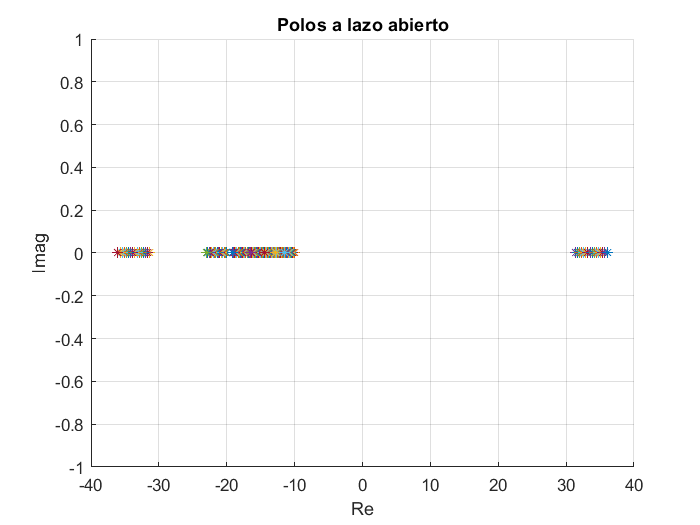

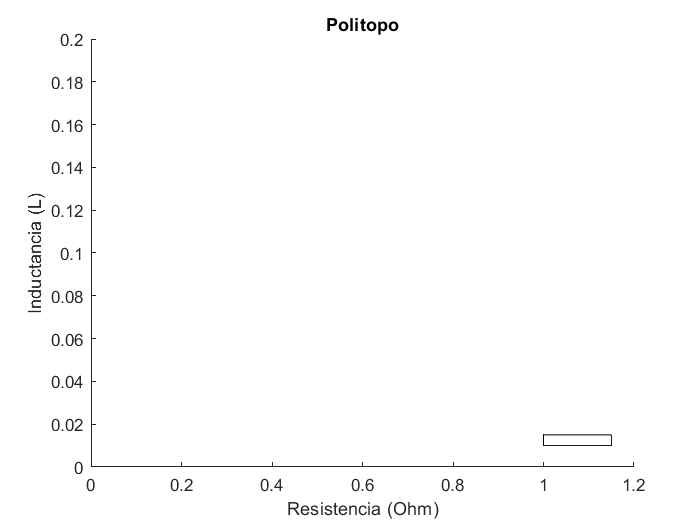

$$A1 = \left(\begin{array}{ccc} 0 & 1 & 0\\ \frac{962361}{980} & 0 & -\frac{981}{350}\\ 0 & 0 & -100 \end{array}\right)$$

$$A2 = \left(\begin{array}{ccc} 0 & 1 & 0\\ \frac{509088969}{392000} & 0 & -\frac{2943}{700}\\ 0 & 0 & -\frac{230}{3} \end{array}\right)$$

$$A3 = \left(\begin{array}{ccc} 0 & 1 & 0\\ \frac{962361}{980} & 0 & -\frac{981}{350}\\ 0 & 0 & -\frac{200}{3} \end{array}\right)$$

$$A4 = \left(\begin{array}{ccc} 0 & 1 & 0\\ \frac{509088969}{392000} & 0 & -\frac{2943}{700}\\ 0 & 0 & -115 \end{array}\right)$$


 Solver for LMI feasibility problems L(x) < R(x)
    This solver minimizes  t  subject to  L(x) < R(x) + t*I
    The best value of t should be negative for feasibility

 Iteration   :    Best value of t so far 
 
     1                        0.121501
     2                        0.014686
***                 new lower bound:    -0.080314
     3                        0.014686
     4                    1.766713e-03
     5                    1.002425e-03
***                 new lower bound: -2.777640e-04
     6                    2.381897e-04
***                 new lower bound: -1.138261e-04
     7                    3.628570e-05
***                 new lower bound: -5.252123e-05
     8                    5.643506e-06
***                 new lower bound: -9.624698e-06
     9                    5.643506e-06
***                 new lower bound: -1.989782e-06
    10                    5.404928e-06
    11                    1.705616e-06
***                 new lower bound: -1.420421e-07
 

S = 	1.0e+-11 *

    0.0001   -0.0014   -0.0001
   -0.0014   -0.4035   -0.0012
   -0.0001   -0.0012   -0.0184


R = 	1.0e+-12 *

   -0.0006   -0.0129   -0.4289


K =     0.7902   -0.0065    2.3300


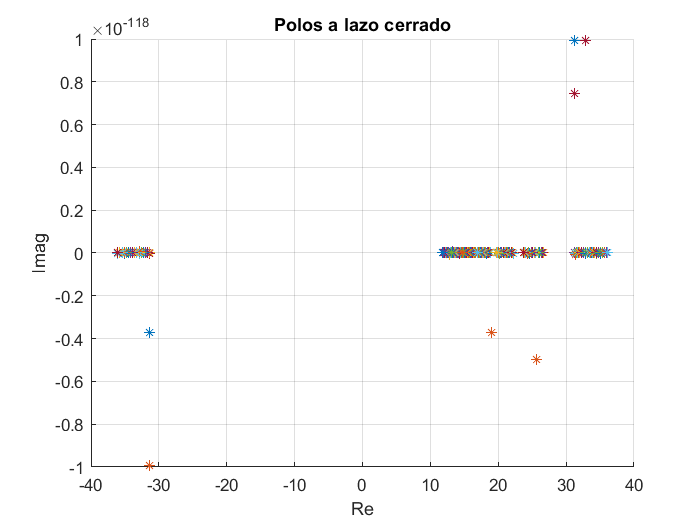

% definimos la variable compleja s
syms s c m R g L V x1 x2 x3 X1 X2 X3 % X mayuscula es para el punto de equilibrio; c = constante; m = masa ; R = resistencia; L = inductancia; V = tensión; g = gravedad
% In
In =  [1 0 0;0 1 0;0 0 1]
% A
A = [0 1 0; (c*X3^2)/(m*X1^2) 0 (-2*c*X3)/(m*X1);0 0 -R/L]
% B
B = [0;0;1/L]
% C 
C = [1 0 0]
% sIn - A 
X = s*In - A
% inversa 
Y = inv(X)



% Tomando como valores variables la masa y la resistencia y valores fijos
% la constante "c", la masa "M" y la tensión "V"

%q1 A(2,1) 
q1 =  (c*(V/R)^2)/(m*(((c*V^2)/(m*g*R^2)))^2);
%q2 A(2,3)
q2 = -1 * ((2*V/R*c)/(m*(c*V^2)/(m*g*R^2)));
%q3 A(3,3)
q3 = -R/L;
%q4 B(3,1)
q4 = 1/L;

% Sustituimos los valores por defecto 

q1 = subs(q1, [c V g m], [0.0001, 7, 9.81 0.05]);
q2 = subs(q2, [c V g m], [0.0001, 7, 9.81 0.05]);


% Localizamos los polos para el caso donde R varia entre 1 y 1.15, la
% inductancia entre 0.01 H y 0.015 H



figure
for r=1:0.01:1.15
   q2f = subs(q2, R, r);
    for l=0.05:0.01:0.1
        q1f = subs(q1, R, r);
        q3f = subs(q3, [R L], [r l]);
        q4f = subs(q4, L, l);
        A=[0 1 0; q1f 0 q2f; 0 0 q3f];
        p=eig(A);
        hold on
        plot(real(p(1)),imag(p(1)),'*')
        plot(real(p(2)),imag(p(2)),'*')
        plot(real(p(3)), imag(p(3)), '*')
    end
end
grid
xlabel('Re'), ylabel('Imag'), title('Polos a lazo abierto')
hold off

% Dibujamos el politopo 
figure
rectangle('Position', [1 0.01 0.15 0.005])
title('Politopo')
xlabel('Resistencia (Ohm)')
ylabel('Inductancia (L)')
axis([0 1.20 0 0.2])


% Creamos la desigualdad lineal matricial 


% Realimentación de estado + reubicación de polos en región R(Alfa,Ro) 
% Theta = 0.

% Planta
A1=[0 1 0;subs(q1, R, 1 ) 0 subs(q2, R, 1); 0 0 subs(q3, [R L], [1 0.01])]

A2=[0 1 0;subs(q1, R, 1.15 ) 0 subs(q2, R, 1.5); 0 0 subs(q3, [R L], [1.15 0.015])]

A3=[0 1 0;subs(q1, R, 1 ) 0 subs(q2, R, 1); 0 0 subs(q3, [R L], [1 0.015])]

A4=[0 1 0;subs(q1, R, 1.15 ) 0 subs(q2, R, 1.5); 0 0 subs(q3, [R L], [1.15 0.01])]

B1=[0; 0; subs(q4, L, 0.01)];

B2=[0; 0; subs(q4, L, 0.015)];

% Especificaciones región reubicación de polos
Alfa=3;
Ro=1;

% Creación sistema LMI
setlmis([])

% Variables LMIs
S=lmivar(1,[3 1]); % S(3,3) simétrica, 3x3 porque A es de 3x3 
R=lmivar(2,[1 3]); % R(1,2) arbitraria, 1x3 porque B es de 1x3

% S > 0

lmiterm([-1 1 1 S],1,1);

% Restricciones asociadas al parámetro Alfa

% 𝑨𝟏𝑺 + 𝑺𝑨𝟏𝑻 + 𝑩1𝑹 + 𝑹𝑩1 + 𝟐𝜶𝑺 < 𝟎
lmiterm([2 1 1 S],A1,1,'s');
lmiterm([2 1 1 R],B1,1,'s');
lmiterm([2 1 1 S],2*Alfa,1);

% 𝑨𝟐𝑺 + 𝑺𝑨𝟐𝑻 + 𝑩2𝑹 + 𝑹𝑩2 + 𝟐𝜶𝑺 < 𝟎
lmiterm([3 1 1 S],A2,1,'s');
lmiterm([3 1 1 R],B2,1,'s');
lmiterm([3 1 1 S],2*Alfa,1);

% 𝑨𝟑𝑺 + 𝑺𝑨𝟑𝑻 + 𝑩2𝑹 + 𝑹𝑩2 + 𝟐𝜶𝑺 < 𝟎
lmiterm([4 1 1 S],A3,1,'s');
lmiterm([4 1 1 R],B2,1,'s');
lmiterm([4 1 1 S],2*Alfa,1);

% 𝑨𝟒𝑺 + 𝑺𝑨𝟒𝑻 + 𝑩1𝑹 + 𝑹𝑩1 + 𝟐𝜶𝑺 < 𝟎
lmiterm([5 1 1 S],A4,1,'s');
lmiterm([5 1 1 R],B1,1,'s');
lmiterm([5 1 1 S],2*Alfa,1);

% Restricciones asociadas al parámetro Ro

% (A1,B1)
lmiterm([6 1 1 S],-Ro,1);
lmiterm([6 1 2 S],A1,1);
lmiterm([6 1 2 R],B1,1);
lmiterm([6 2 2 S],-Ro,1);

% (A2,B2)
lmiterm([7 1 1 S],-Ro,1);
lmiterm([7 1 2 S],A2,1);
lmiterm([7 1 2 R],B2,1);
lmiterm([7 2 2 S],-Ro,1);

% (A3,B2)
lmiterm([8 1 1 S],-Ro,1);
lmiterm([8 1 2 S],A3,1);
lmiterm([8 1 2 R],B2,1);
lmiterm([8 2 2 S],-Ro,1);

% (A4,B1)
lmiterm([9 1 1 S],-Ro,1);
lmiterm([9 1 2 S],A4,1);
lmiterm([9 1 2 R],B1,1);
lmiterm([9 2 2 S],-Ro,1);


% Ejecución del solver
LMISYS=getlmis;
[tmin,xfeas]=feasp(LMISYS);

% Solución
S=dec2mat(LMISYS,xfeas,S);
R=dec2mat(LMISYS,xfeas,R);
S
R
K=R*inv(S)


% Polos a lazo cerrado del sistema  politópico

syms R
figure
for r=1:0.01:1.15
   q2f = subs(q2, R, r);
    for l=0.05:0.01:0.1
        q1f = subs(q1, R, r);
        q3f = subs(q3, [R L], [r l]);
        q4f = subs(q4, L, l);
        A=[0 1 0; q1f 0 q2f; 0 0 q3f];
        p=eig(A + subs(B,L,l) *K);
        hold on
        plot(real(p(1)),imag(p(1)),'*')
        plot(real(p(2)),imag(p(2)),'*')
        plot(real(p(3)), imag(p(3)), '*')
    end
end
grid
xlabel('Re'), ylabel('Imag'), title('Polos a lazo cerrado')
hold off